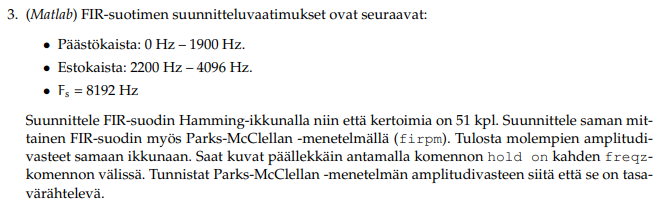

Fs=8192;
N=51;
fc=(1900+2200)/2/Fs

fc = 0.2502

d=fir1(N-1,2*fc,"low",hamming(N))

d =     0.0010    0.0000   -0.0013   -0.0001    0.0021    0.0001   -0.0034   -0.0001    0.0055    0.0002   -0.0084   -0.0002    0.0125    0.0003   -0.0181   -0.0003    0.0260    0.0004   -0.0378   -0.0004    0.0580    0.0005   -0.1026   -0.0005    0.3168    0.5000    0.3168   -0.0005   -0.1026    0.0005    0.0580   -0.0004   -0.0378    0.0004    0.0260   -0.0003   -0.0181    0.0003    0.0125   -0.0002   -0.0084    0.0002    0.0055   -0.0001   -0.0034    0.0001    0.0021   -0.0001   -0.0013    0.0000


freqz(d)
 
%Parks-McCellen
f=[0 1900 2200 4096]/Fs

f =          0    0.2319    0.2686    0.5000


a=[1 1 0 0]

a =      1     1     0     0


b=firpm(N-1,2*f,a)

b =     0.0078    0.0006   -0.0056    0.0002    0.0064    0.0006   -0.0092    0.0001    0.0110    0.0007   -0.0148   -0.0000    0.0181    0.0007   -0.0240   -0.0001    0.0307    0.0007   -0.0423   -0.0002    0.0608    0.0007   -0.1048   -0.0002    0.3175    0.5008    0.3175   -0.0002   -0.1048    0.0007    0.0608   -0.0002   -0.0423    0.0007    0.0307   -0.0001   -0.0240    0.0007    0.0181   -0.0000   -0.0148    0.0007    0.0110    0.0001   -0.0092    0.0006    0.0064    0.0002   -0.0056    0.0006


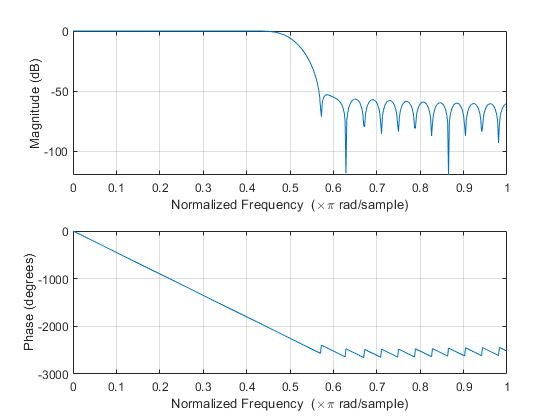

hold on

freqz(b)

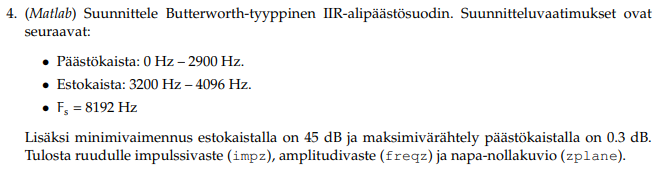

Fs=8192

Fs = 8192

Wp=2900/Fs%paastokaistan rajataajuus

Wp = 0.3540

Ws=3200/Fs%Estokaistan rajataajuus

Ws = 0.3906

Rp=0.3%varahtely paastokaistalla

Rp = 0.3000

Rs=45%varahtely stokaistalla

Rs = 45

%Butterworth filter order and cutoff frequency
[n,Wn]=buttord(2*Wp,2*Ws,Rp,Rs)

n = 21

Wn = 0.7266

[b,a]=butter(n,Wn, "low")

b =     0.0025    0.0524    0.5238    3.3173   14.9281   50.7554  135.3477  290.0307  507.5537  733.1332  879.7598  879.7598  733.1332  507.5537  290.0307  135.3477   50.7554   14.9281    3.3173    0.5238    0.0524    0.0025


a =     1.0000    9.5120   44.8590  138.5957  313.2955  549.1277  772.6331  892.1773  857.7281  692.8348  472.6563  272.8639  133.1687   54.7262   18.8005    5.3383    1.2319    0.2254    0.0315    0.0032    0.0002    0.0000


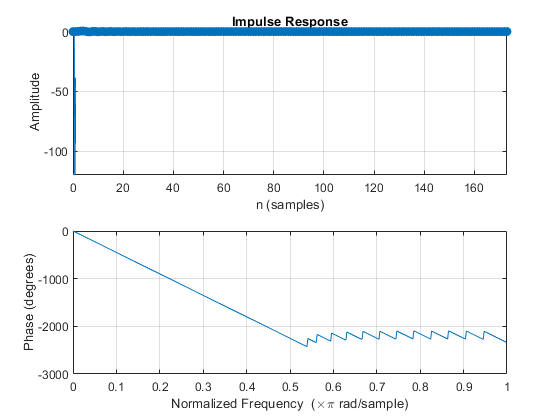

impz(b,a)

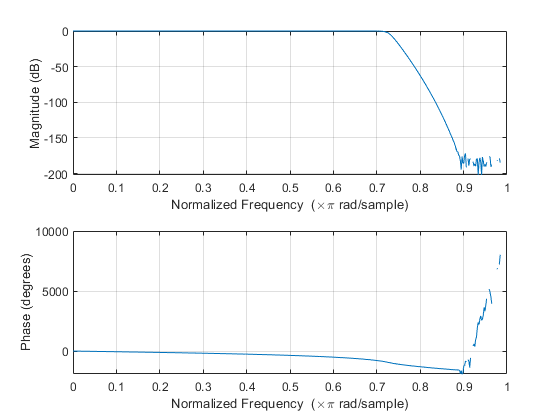

freqz(b,a)

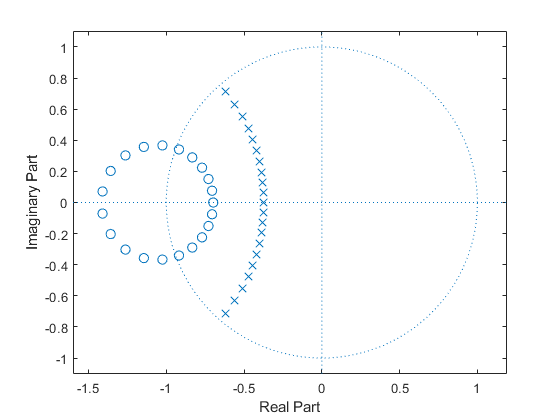

zplane(b,a)

Fs=8192

Fs = 8192

Wp=2900/Fs%paastokaistan rajataajuus

Wp = 0.3540

Ws=3200/Fs%Estokaistan rajataajuus

Ws = 0.3906

Rp=0.3%varahtely paastokaistalla

Rp = 0.3000

Rs=45%varahtely stokaistalla

Rs = 45

%Minimum order for elliptic filters
[N Wn]=ellipord(2*Wp,2*Ws,Rp,Rs)

N = 6

Wn = 0.7080

[b,a]=ellip(N,Rp,Rs,Wn,"low")

b =     0.2108    1.0506    2.3650    3.0471    2.3650    1.0506    0.2108


a =     1.0000    2.2474    3.1837    2.4230    1.3391    0.3673    0.1016


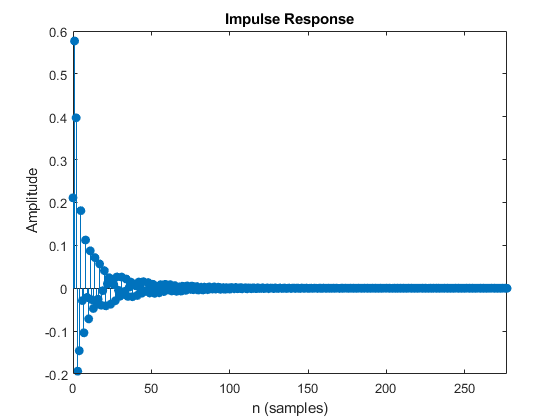

impz(b,a)

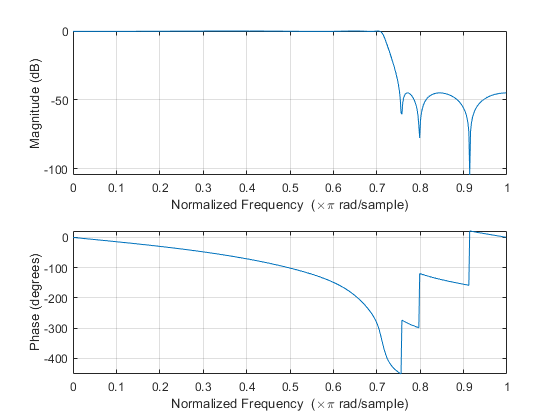

freqz(b,a)

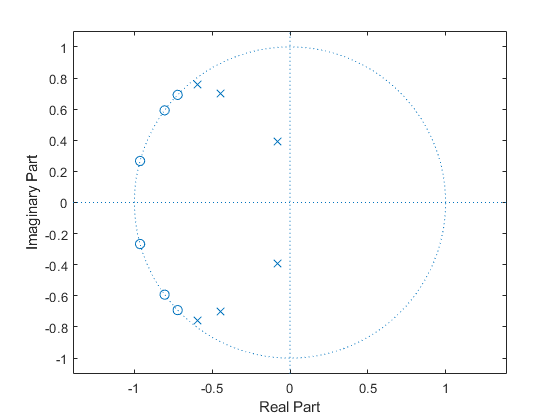

zplane(b,a)